clc; clear variables; close all;

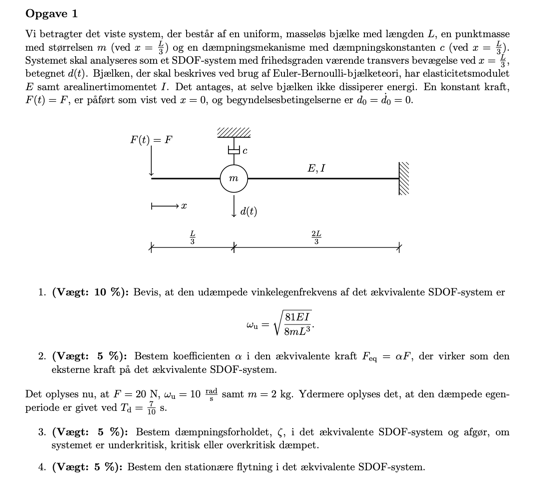

1.1 Idet vi kalder kraftens placering 2 og massens placering 1, har vi fra D'Alemberts princip at vi kan skrive flytningen af massen $d(t)$ som


$$d\left(t\right)=\delta_{12} F\left(t\right)-\delta_{11} m\ddot{d} \left(t\right)-\delta_{11} c\dot{d} \left(t\right)\;\;\;\Rightarrow \;\;\;\;m\ddot{d} \left(t\right)+c\dot{d} \left(t\right)+\frac{1}{\delta_{11} }d\left(t\right)=\frac{\delta_{12} }{\delta_{11} }F\left(t\right)$$


Altså har vi at $k_{eq} =  \frac{1}{\delta_{11}}$ og $F_{eq} = \frac{\delta_{12}}{\delta_{11}} F(t)$. Den udæmpede vinkelegenfrekvens af det ækvivalente SDOF system er givet ved:


$$\omega_u =\sqrt{\frac{k_{\textrm{eq}} }{m}}=\sqrt{\frac{1}{m\delta_{11} }}$$


Vi skal altså finde det fleksibilitetskoefficienten $\delta_{11}$. Fra American Wood Council, *Beam Design Formulas with Shear and Moment Diagrams*, AF&PA, Design Aid No. 6, 2007 s. 8 har vi at forskydningen forårsaget af en enhedslast placeret ved et punkt 2/3 af længden af en knægtbjælke er:


$$\delta_{11} =\frac{{\left(\frac{2L}{3}\right)}^3 }{3\textrm{EI}}=\frac{{8L}^3 }{81\textrm{EI}}$$


Altså får vi at


$$\omega_u =\sqrt{\frac{1}{m\cdot \frac{8L^3 }{81\;E\;I}}}=\sqrt{\frac{81\;E\;I}{8m\;L^3 }}$$


Altså er det vist.

1.2 Den ækvivalente kraft er ovenfor vist til at være $F_{eq} = \frac{\delta_{12}}{\delta_{11}} F(t) $. Vi har allerede fundet $\delta_{11}$ og vi mangler derfor blot at finde fleksibilitetskoefficienten $\delta_{12}$. Fra samme sted som ovenfor har vi at forskydningen ved 1 på en knægtbjælke forårsaget af en enhedslast i punkt 2 er


$$\delta_{12} =\frac{14L^3 }{81\textrm{EI}}$$


Altså har vi at


$$\alpha =\frac{\delta_{12} }{\delta_{11} }=\frac{14}{8}=\frac{7}{4}$$


Altså er $\alpha = 7/4$.

1.3 Vi har at den dæmpede egenperiode er relateret til den dæmpede egenfrekvens som


$$T_d =\frac{2\pi }{\omega_d }\;\;\;\Rightarrow \;\;\;\omega_d =\frac{2\pi \;}{T_d }$$


Den dæmpede egenperiode er relateret til den udæmpede igennem følgende formel, hvor dæmpningsforholdet også indgår:


$$\omega_d =\omega_u \sqrt{1-\zeta^2 }\;\;\;\Rightarrow \;\;\;\zeta =\sqrt{1-\frac{\omega_d^2 }{\omega_u^2 }}=\sqrt{1-\frac{4\pi^2 }{T_d^2 \omega_u^2 }}$$


T_d = 7/10; %s
omega_u = 10; %rad/s

zeta = sqrt(1 - 4 * pi^2/(T_d^2 * omega_u^2))

zeta = 0.4408

Altså er dæmpningsforholdet $\zeta \approx 0.44$, hvorfor systemet er underkritisk dæmpet.

1.4 Eftersom $F(t)$ er konstant er det stationære flytningsrespons blot


$$d_{\textrm{ss}} =\frac{F_{\textrm{eq}} }{k_{\textrm{eq}} }$$


Vores ækvivalente dæmpning kan findes fra relationen:


$$\omega_u =\sqrt{\frac{k_{\textrm{eq}} }{m}}\;\;\;\Rightarrow \;\;\;\;k_{\textrm{eq}} =\omega_u^2 m$$


Dette regnes i MatLab til

F = 20; %N
alpha = 7/4;
m = 2; %kg

F_eq = alpha * F;
k_eq = omega_u^2 * m;

d_ss = F_eq/k_eq

d_ss = 0.1750

Altså er den stationære flytningsrespons $d_{ss} = 0.175 \, m = 17.5 \, cm$.

clc; clear variables; close all;

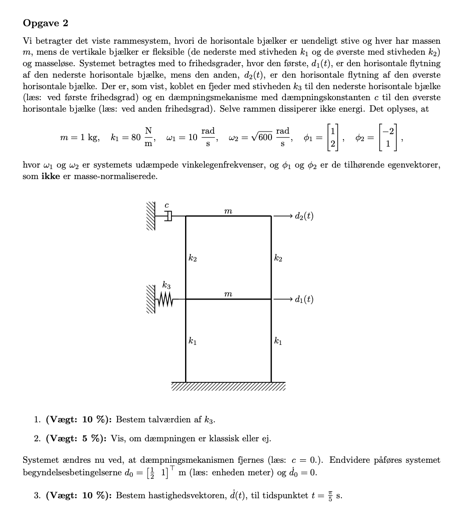

2.1 Vi har vores spektralmatrice


$$\Lambda =\left\lbrack \begin{array}{cc}
{10}^2  & 0\\
0 & 600
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
100 & 0\\
0 & 600
\end{array}\right\rbrack$$


og modalmatrice


$$\Phi =\left\lbrack \begin{array}{cc}
1 & -2\\
2 & 1
\end{array}\right\rbrack$$


Derudover har vi at:


$$K\Phi =M\Phi \Lambda \;\;\;\;\;\Rightarrow \;\;\;\;\;K=M\Phi \Lambda \Phi^{-1}$$


Altså kan $K$ findes i Matlab som

Lambda = [100    0; 0    600];
Phi    = [1     -2; 2      1];
M      = [1      0; 0      1];

K = M*Phi*Lambda*Phi^-1

K =    500  -200
  -200   200


Altså er stivhedsmatricen $K=\left\lbrack \begin{array}{cc}
500 & -200\\
-200 & 200
\end{array}\right\rbrack$.

Fra Newtons 2. lov kan vi opskrive følgende to sammenhænge for de to frihedsgrader idet vi udelader at skrive at positioner og dets afledte, $d, \dot{d}, \ddot{d}$ er tidsafhængige af notationsmæssige årsager:


$$m\ddot{d_1 } =-2k_1 d_1 -k_3 d_1 +2k_2 \left(d_2 -d_1 \right)\;\;\;\;\;\Rightarrow \;\;\;\;\;m\ddot{d_1 } +2k_1 d_1 +2k_2 d_1 +k_3 d_1 -2k_2 d_2 =0$$



$$m\ddot{d_2 } =-2k_2 \left(d_2 -d_1 \right)-c\dot{d_2 } \;\;\;\;\;\;\;\;\Rightarrow \;\;\;\;\;m\ddot{d_2 } -2k_2 d_1 +2k_2 d_2 +c\dot{d_2 } =0$$


Disse kan samles til


$$\left\lbrack \begin{array}{cc}
m & 0\\
0 & m
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ddot{d_1 } \\
\ddot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & c
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{d_1 } \\
\dot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
2k_1 +2k_2 +k_3  & -2k_2 \\
-2k_2  & 2k_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
d_1 \\
d_2 
\end{array}\right\rbrack =0$$


Altså er vores stivhedsmatrice:


$$K=\left\lbrack \begin{array}{cc}
2k_1 +2k_2 +k_3  & -2k_2 \\
-2k_2  & 2k_2 
\end{array}\right\rbrack$$


Dermed kan $k_3$ findes vha. Matlab som:

syms k_2 k_3

k_1 = 80;

K_sym = [2*k_1 + 2*k_2 + k_3   -2*k_2; -2*k_2    2*k_2];
K_val = [500                     -200;   -200      200];

[k_2, k_3] = solve(K_sym == K_val, [k_2, k_3])

$$k\_2 = 100$$

$$k\_3 = 140$$

Altså er $k_3 = 140 \, N/m$. 

2.2 Ovenfor er vores dæmpningsmatrice bestemt til $C=\left\lbrack \begin{array}{cc}
0 & 0\\
0 & c
\end{array}\right\rbrack$. Vi undersøger nu om $\tilde{C}$ er diagonal, idet $\tilde{C}$ er fundet som


$$\tilde{C} =\Phi^T C\Phi \;$$


Altså

syms c

C = [0    0; 0    c];

C_tilde = Phi' * C * Phi

$$C\_tilde = \left(\begin{array}{cc} 4\,c & 2\,c\\ 2\,c & c \end{array}\right)$$

Da $\tilde{C} =\left\lbrack \begin{array}{cc}
4c & 2c\\
2c & c
\end{array}\right\rbrack$ er vores modale dæmpningsmatrice ikke diagonal og dæmpningen er derfor ikke klassisk. 

2.3 Vi indser at begyndelsespositionen ligger i første egensvingningsform idet


$$d_0 =\frac{1}{2}\phi_1$$


Altså kan vores generelle løsning reduceres fra


$$d\left(t\right)=\phi_1 \left(A_1 \;\cos \left(\omega_1 t\right)+B_1 \sin \left(\omega_1 t\right)\right)+\phi_2 \left(A_2 \cos \left(\omega_2 t\right)+B_2 \sin \left(\omega_2 t\right)\right)$$


til


$$d\left(t\right)=\phi_1 \left(A_1 \;\cos \left(\omega_1 t\right)+B_1 \sin \left(\omega_1 t\right)\right)$$


Idet vores begyndelseshastighed er 0 udgår sinusleddet også og vores løsning bliver derfor


$$d\left(t\right)=\phi_1 A_1 \;\cos \left(\omega_1 t\right)=\frac{1}{2}\phi_1 \cos \left(\omega_t t\right)=\frac{1}{2}\left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack \cos \left(10t\right)$$


Hvilket differentieres i Matlab for at finde hastighedsudtrykket:

syms t

d(t) = 1/2 * [1; 2] * cos(10 * t);

dd(t) = diff(d(t))

$$dd(t) = \left(\begin{array}{c} -5\,\sin\left(10\,t\right)\\ -10\,\sin\left(10\,t\right) \end{array}\right)$$


dd(pi/5)

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

Altså er vores hastighed ved tiden $t = \pi/5$, $\dot{d} \left(\frac{\pi }{5}\right)=\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$.

clear variables; clc; close all;

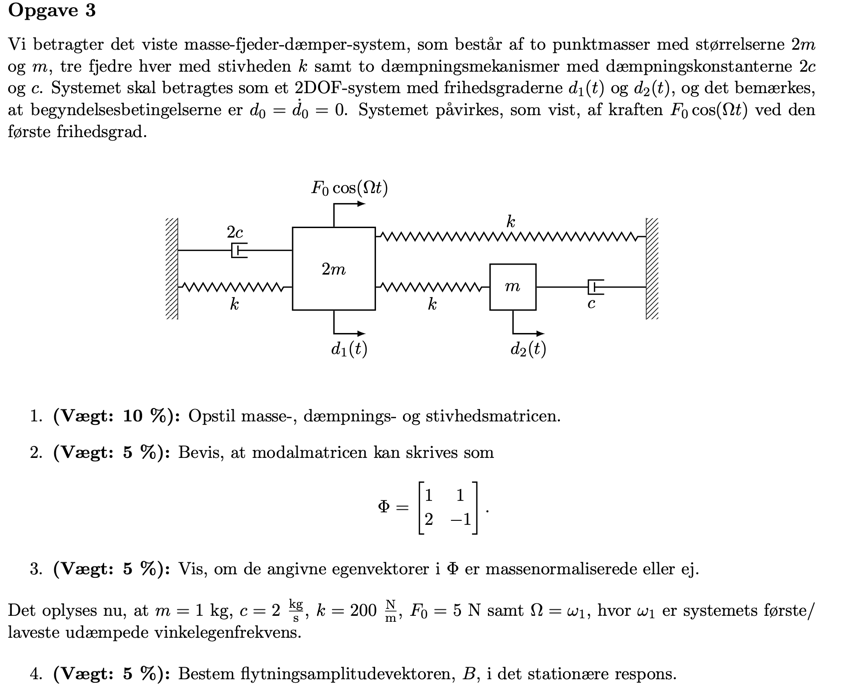

3.1 Fra Newtons 2. lov har vi følgende to ligninger, idet vi udelader at skrive tidsafhængigheden $(t)$ af positionen og dens afledte af notationsmæssige årsager.


$$2m\;\ddot{d_1 } =-2c\dot{d_1 } +{\mathrm{kd}}_1 +{\mathrm{kd}}_1 +k\left(d_2 -d_1 \right)\;\;\;\Rightarrow \;\;\;2m\ddot{d_2 } +2c\dot{d_1 } +3{k\;d}_1 -{k\;d}_2 =0$$



$$m\ddot{d_2 } =-k\left(d_2 -d_1 \right)-c\dot{d_2 } \;\;\;\;\;\;\;\Rightarrow \;\;\;\;\;m\ddot{d_2 } +c\dot{d_2 } -{k\;d}_1 +k\;d_2 =0$$


Hvilket kan samles til


$$\left\lbrack \begin{array}{cc}
2m & 0\\
0 & m
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ddot{d_1 } \\
\ddot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
2c & 0\\
0 & c
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{d_1 } \\
\dot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
3k & -k\\
-k & k
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
d_1 \\
d_2 
\end{array}\right\rbrack =0$$


Hvoraf vi kan aflæse $M=\left\lbrack \begin{array}{cc}
2m & 0\\
0 & m
\end{array}\right\rbrack ,\;C=\left\lbrack \begin{array}{cc}
2c & 0\\
0 & c
\end{array}\right\rbrack ,\;\;K=\left\lbrack \begin{array}{cc}
3k & -k\\
-k & k
\end{array}\right\rbrack$

3.2 Modalmatricen er sammensat af de to egenvektorer knyttet til egenvektorproblemet


$$\left(K-\omega_j^2 M\right)\phi_j =0$$


hvor egenværdierne $\omega_j$ kommer fra egenværdiproblemet

$\det \left(K-\omega^2 M\right)=0$.

Hele egensystemet kan nemt løses i Matlab som:

syms m k positive

M = [2*m    0;  0    m];
K = [3*k   -k; -k    k];

[Phi, Lambda] = eig(M\K)

$$Phi = \left(\begin{array}{cc} -1 & \frac{1}{2}\\ 1 & 1 \end{array}\right)$$

$$Lambda = \left(\begin{array}{cc} \frac{2\,k}{m} & 0\\ 0 & \frac{k}{2\,m} \end{array}\right)$$

Her får vi altså de to egenvektorer $\phi_1 =\left\lbrack \begin{array}{c}
-1\\
1
\end{array}\right\rbrack ,\phi_2 =\left\lbrack \begin{array}{c}
\frac{1}{2}\\
1
\end{array}\right\rbrack$. Vi kan selv bestemme rækkefølgen af dem og skalere dem frit som vi vil, hvis vi skriver modalmatricen som $\Phi =\left\lbrack \begin{array}{cc}
2\phi_2  & -1\phi_1 
\end{array}\right\rbrack$ får vi:


$$\Phi =\left\lbrack \begin{array}{cc}
1 & 1\\
2 & -1
\end{array}\right\rbrack$$


Altså er det vist.

3.3 For at undersøge om egenvektorerne angivet i $\Phi$ er massenormaliserede regner vi modalmassematricen


$$\tilde{M} =\Phi^T M\Phi$$


Phi = [1    1; 2    -1];

M_tilde = Phi'*M*Phi

$$M\_tilde = \left(\begin{array}{cc} 6\,m & 0\\ 0 & 3\,m \end{array}\right)$$

Da $\tilde{M} \not= I$ er egenvektorerne i $\Phi$ ikke massenormaliserede.

3.4

Vi har for en harmonisk respons $F\left(t\right)=F_0 \cos \left(\omega \;t\right)$, at flytningsamplituden i den stationære respons $B_j$ er den j'te komponent af $|{H\left(\omega \;\right)F}_0 |$, hvor $H(\omega)$ er den dynamiske fleksibilitetsmatrice defineret som


$$H\left(\omega \right)={\left(-M\omega^2 +C\;i\omega +K\right)}^{-1}$$


Vores lastfrekvens $\Omega = \omega_1$ og altså skal den laveste komponent af $\Lambda =\left\lbrack \begin{array}{cc}
\frac{2k}{m} & 0\\
0 & \frac{k}{2m}
\end{array}\right\rbrack$ (fundet i opgave 3.2) findes. Disse regnes numerisk i Matlab som:

m_num = 1; %kg
k_num = 200; %N/m

Lambda_num = subs(Lambda, [k, m], [k_num, m_num]);

Altså ser vi at 


$$\Lambda =\left\lbrack \begin{array}{cc}
\omega_1^2  & 0\\
0 & \omega_2^2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
100 & 0\\
0 & 400
\end{array}\right\rbrack$$


Altså har vi at $\Omega = \omega_1 = \sqrt{100} = 10$. Dermed kan vi nu indsætte i formlen for fleksibilitetsmatricen

Omega = 10; %rad/s
c = 2; %kg/s

C = [2*c    0; 0    c];

H = subs((- M * Omega^2 + C * 1i * Omega + K)^-1,[k, m],[k_num, m_num]);

Og dernæst har vi at


$$B_j =|H\left(\omega \right)F_0 |_j$$


F_0 = [5; 0]; %N
B = double(abs(H * F_0))

B =     0.0424
    0.0831


Altså har vi vores flytningsamplitudevektor i det stationære respons

$B\approx \left\lbrack \begin{array}{c}
0\ldotp 04\\
0\ldotp 08
\end{array}\right\rbrack m=\left\lbrack \begin{array}{c}
4\\
8
\end{array}\right\rbrack \mathrm{cm}$.

clc; clear variables; close all;

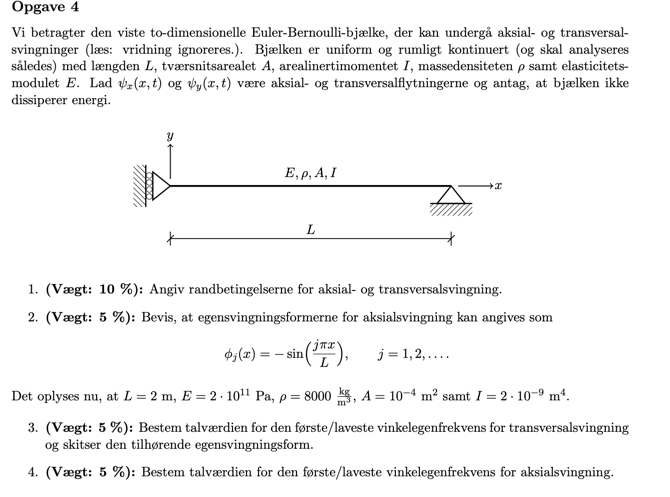

4.1 Euler Bernoulli transversalsvingning er 4. orden i $x$ og vi skal derfor have 4 randbetingelser for $\psi_y$. Aksialsvingning er kun 2. orden og vi skal derfor kun have 2 randbetingelser for $\psi_x$. Begge understøtninger forhindrer aksial bevægelse


$$\psi_x \left(0,t\right)=0\;\;\;\Rightarrow \;\phi_j^x \left(0\right)=0$$



$$\psi_x \left(L,t\right)=0\;\;\;\Rightarrow \;\phi_j^x \left(L\right)=0$$


Dette er vores randbetingelser for aksialsvingning. Vi mangler derfor nu kun at finde de 4 randbetingelser for transversalsvingningen $\psi_y$.

Den højre understøtning forhindrer transversal bevægelse:


$$\psi_y \left(L,t\right)=0\;\;\;\Rightarrow \;\phi_j^y \left(L\right)=0$$


Den venstre understøtning fungerer som en fri ende for transversalsvining således at forskydningskraften $V=0$ her. Altså


$$\frac{d^3 \;\psi_y \left(0,t\right)}{x^3 }=0\;\;\;\Rightarrow \frac{d^3 \phi_j^y \left(0\right)}{x^3 }=0$$


Ingen af de to understøtning forhindrer ej heller et moment for transversalsvingning således at


$$\frac{d^2 \psi_y \left(0,t\right)}{x^2 }=0\;\;\;\Rightarrow \frac{d^2 \phi_j^y \left(0\right)\;\;\;}{x^2 }=0$$



$$\frac{d^2 \psi_y \left(L,t\right)}{x^2 }=0\;\;\;\Rightarrow \frac{d^2 \phi_j^y \left(L\right)\;\;\;}{x^2 }=0$$


Altså er vores randbetingelser for aksialsvingning:


$$\psi_x \left(0,t\right)=0\;\;\;\Rightarrow \;\phi_j^x \left(0\right)=0$$



$$\psi_x \left(L,t\right)=0\;\;\;\Rightarrow \;\phi_j^x \left(L\right)=0$$


Og vores randbetingelser for transversalsvningning:


$$\psi_y \left(L,t\right)=0\;\;\;\Rightarrow \;\phi_j^y \left(L\right)=0$$



$$\frac{d^2 \psi_y \left(0,t\right)}{x^2 }=0\;\;\;\Rightarrow \frac{d^2 \phi_j^y \left(0\right)\;\;\;}{x^2 }=0$$



$$\frac{d^2 \psi_y \left(L,t\right)}{x^2 }=0\;\;\;\Rightarrow \frac{d^2 \phi_j^y \left(L\right)\;\;\;}{x^2 }=0$$



$$\frac{d^3 \;\psi_y \left(0,t\right)}{x^3 }=0\;\;\;\Rightarrow \frac{d^3 \phi_j^y \left(0\right)}{x^3 }=0$$


4.2 Vi verficerer at det givne udtryk overholder randbetingelserne:

syms L
syms j integer
phi_j = @(x) - sin (j * pi * x / L);

phi_j(0)

$$ans = 0$$

simplify(phi_j(L))

$$ans = 0$$

Altså er det vist

4.3 Den første transversalsvingingsform er en stivlegemebevægelse, hvorfor $\omega_1 = 0$.

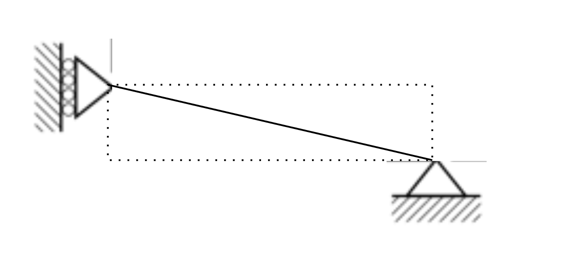

4.4 For aksialsvingingen har vi at


$$\omega_j =\frac{j\pi \;}{L}\eta =\frac{j\pi }{L}\sqrt{\frac{E}{\rho }}$$


Den laveste vinkelegenfrekvens er for $j = 1$, altså:

E = 2e11; %Pa
rho = 8000; %kg/m^3
L = 2; %m

omega_1 = pi/L * sqrt(E/rho)

omega_1 = 7.8540e+03

Altså er den laveste vinkelegenfrekvens for aksialsvingning $\omega_1 = 7854$ rad/s.